### Задание 4. Тележка и меандр.

Начальные данные для задания:

A = [0 1; 
    0 0];
B = [0; 1];
Cz = [1 0];

C = [1 0;]

C =      1     0


D = [0]

D = 0


Bf = 0;

Dz = -[4/(1*pi) 0 4/(3*pi) 0 4/(5*pi) 0 4/(7*pi) 0]

Dz =    -1.2732         0   -0.4244         0   -0.2546         0   -0.1819         0


G = [0 1 0 0 0 0 0 0; 
    -1 0 0 0 0 0 0 0; 
    0 0 0 3 0 0 0 0; 
    0 0 -3 0 0 0 0 0; 
    0 0 0 0 0 5 0 0; 
    0 0 0 0 -5 0 0 0;
    0 0 0 0 0 0 0 7;
    0 0 0 0 0 0 -7 0 ;]

G =      0     1     0     0     0     0     0     0
    -1     0     0     0     0     0     0     0
     0     0     0     3     0     0     0     0
     0     0    -3     0     0     0     0     0
     0     0     0     0     0     5     0     0
     0     0     0     0    -5     0     0     0
     0     0     0     0     0     0     0     7
     0     0     0     0     0     0    -7     0


mat2tex(G,2);

\begin{bmatrix}
    0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 \\
    -1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \\
    0 & 0 & 0 & 3 & 0 & 0 & 0 & 0 \\
    0 & 0 & -3 & 0 & 0 & 0 & 0 & 0 \\
    0 & 0 & 0 & 0 & 0 & 5 & 0 & 0 \\
    0 & 0 & 0 & 0 & -5 & 0 & 0 & 0 \\
    0 & 0 & 0 & 0 & 0 & 0 & 0 & 7 \\
    0 & 0 & 0 & 0 & 0 & 0 & -7 & 0 \\
\end{bmatrix}


w_0 = [0; 1; 0; 1; 0; 1; 0; 1];
x_0 = 0

x_0 = 0

eig(G)

ans =    0.0000 + 1.0000i
   0.0000 - 1.0000i
   0.0000 + 3.0000i
   0.0000 - 3.0000i
   0.0000 + 5.0000i
   0.0000 - 5.0000i
   0.0000 + 7.0000i
   0.0000 - 7.0000i


Q = eye(2);
R = 1;
[K1,~,~] = lqr(A, B, Q, R);
K1 = -K1

K1 =    -1.0000   -1.7321


eig(A + B*K1)

ans =   -0.8660 + 0.5000i
  -0.8660 - 0.5000i



cvx_begin sdp;
variable P(2,8);
variable Y(1,8);

P*G - A*P == B*Y;
Cz*P + Dz == 0;
cvx_end;

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 



K2 = Y - K1*P

K2 =    -0.0000    2.2053   -3.3953    2.2053   -6.1115    2.2053   -8.7308    2.2053


mat2tex(K2,2);

\begin{bmatrix}
    0 & 2.21 & -3.4 & 2.21 & -6.11 & 2.21 & -8.73 & 2.21 \\
\end{bmatrix}


**Пример разложения в ряд Фурье...**

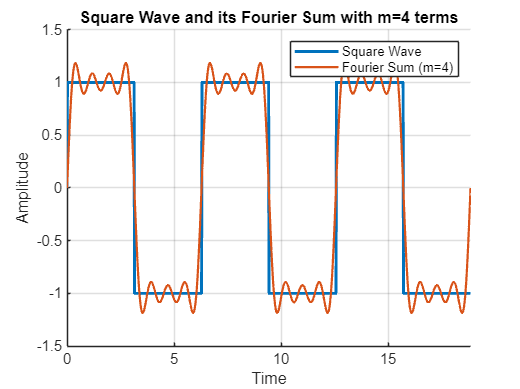

% Параметры меандра, которого мы будем аппроксимировать рядом Фурье
T = 2*pi;          % Period of the square wave
m = 4;             % Number of terms in the partial Fourier sum
t = linspace(0, 3*T, 1000); % Time vector (3 periods)

% Create the square wave
square_wave = sign(sin(t));

% Calculate the partial Fourier sum
% n = {1, 3, 5, 7}
fourier_sum = zeros(size(t));
for n = 1:2:2*m-1  % Only odd harmonics for square wave
    fourier_sum = fourier_sum + (4/(pi*n)) * sin(n*t);
end

figure;
hold on;
plot(t, square_wave, 'LineWidth', 2, 'DisplayName', 'Square Wave');
plot(t, fourier_sum, 'LineWidth', 1.5, 'DisplayName', ['Fourier Sum (m=' num2str(m) ')']);
hold off;

title(['Square Wave and its Fourier Sum with m=' num2str(m) ' terms']);
xlabel('Time');
ylabel('Amplitude');
legend('show');
grid on;
xlim([0, 3*T]);

### Делаем какие-то графики

out = sim('ex4.slx','ReturnWorkspaceOutputs','on'); % same as ex1.slx file
t = out.tout;
x = out.x.data';

square_wave = sign(sin(t));

% Calculate the partial Fourier sum --> n = {1, 3, 5, 7} in our case
fourier_sum = zeros(size(t));
for n = 1:2:2*m-1  % Only odd harmonics for square wave
    fourier_sum = fourier_sum + (4/(pi*n)) * sin(n*t);
end

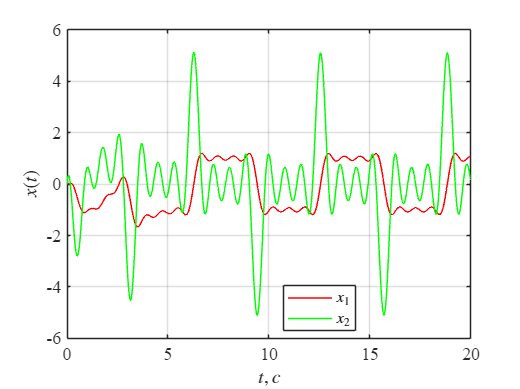

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, x(1, :), 'r', 'LineWidth', 1.0);
hold on;
plot(t, x(2, :), 'g', 'LineWidth', 1.0);
title(' ')
xlabel('$t,c$','Interpreter','latex')
ylabel('$x(t)$', 'Interpreter','latex')
grid on
legend('$x_1$','$x_2$', ...
    'Location','best', 'Interpreter','latex')
save_file("x10")

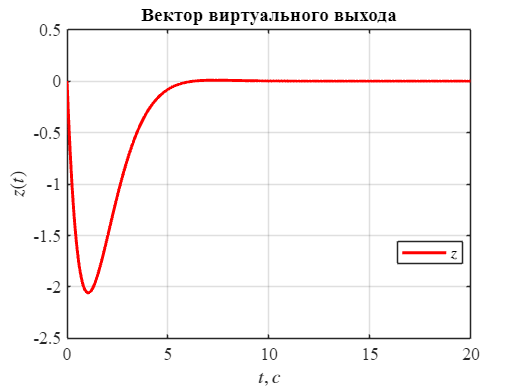

z = out.z.data;
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, z, 'r', 'LineWidth', 2);
title('Вектор виртуального выхода')
xlabel('$t,c$','Interpreter','latex')
ylabel('$z(t)$', 'Interpreter','latex')
grid on
legend('$z$', ...
    'Location','best', 'Interpreter','latex')
save_file("z10")

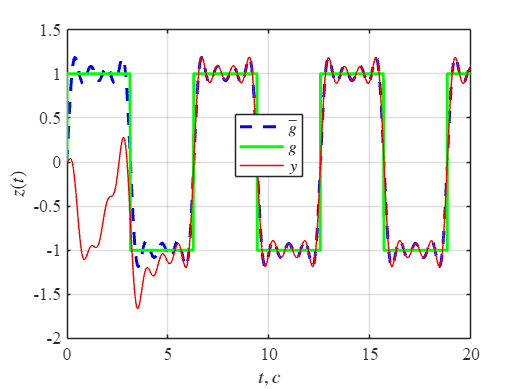

z = out.z.data;
y = out.y.data;
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, fourier_sum, 'b--', 'LineWidth', 2.0); hold on;
plot(t, square_wave, 'g', 'LineWidth', 2); hold on;
plot(t, y, 'r', 'LineWidth', 1.0); 

title(' ')
xlabel('$t,c$','Interpreter','latex')
ylabel('$z(t)$', 'Interpreter','latex')
grid on
legend('$\bar{g}$', '$g$', '$y$',...
    'Location','best', 'Interpreter','latex')

save_file("y_compare")

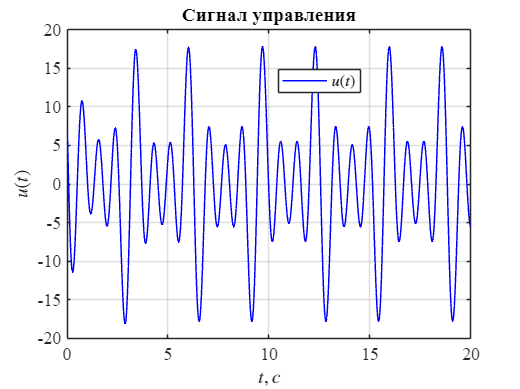

u = out.u.data;
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(t, u, 'b', 'LineWidth', 1.0);
title('Сигнал управления')
xlabel('$t,c$','Interpreter','latex')
ylabel('$u(t)$', 'Interpreter','latex')
grid on
legend('$u(t)$', ...
    'Location','best', 'Interpreter','latex')
save_file("u10")

**Функция, чтобы сохранить картинку в папку**

function save_file(name)
    path = 'D:\Math\control_theory\control_theory_labs\lab12\latex12\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');
end